Préliminaire 2

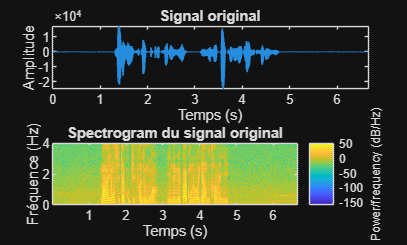

% Chargement des données et paramètres
data = load('fcno03fz.mat');
s = data.fcno03fz(:);
N = length(s);
n = (0:N-1) / 8000;  % echantillonage de 44100 hz car signal de parole

% Génération des signaux bruités
bruit5 = generer_bruits(s, 5);
s_bruit5 = s + bruit5;

bruit10 = generer_bruits(s, 10);
s_bruit10 = s + bruit10;

bruit15 = generer_bruits(s, 15);
s_bruit15 = s + bruit15;

% Figure pour le signal original
figure()
subplot(2, 1, 1)
plot(n, s)
title('Signal original')
xlabel('Temps (s)')
ylabel('Amplitude')
xlim([0 max(n)]);
ylim([min(s) max(s)]);

subplot(2, 1, 2)
spectrogram(s, 256, [], [], 8000, 'yaxis');

title('Spectrogram du signal original')
xlabel('Temps (s)')
ylabel('Fréquence (Hz)');

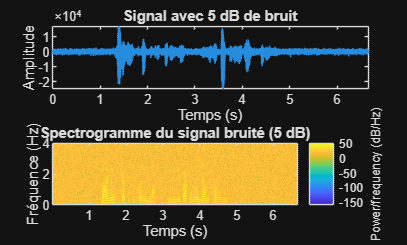


% Figure pour le signal bruité (par exemple avec 5 dB de bruit)
figure()
subplot(2, 1, 1)
plot(n, s_bruit5)
title('Signal avec 5 dB de bruit')
xlabel('Temps (s)')
ylabel('Amplitude')
xlim([0 max(n)]);
ylim([min(s_bruit5) max(s_bruit5)]);

subplot(2, 1, 2)
spectrogram(s_bruit5, 256, [], [], 8000, 'yaxis');
title('Spectrogramme du signal bruité (5 dB)')
xlabel('Temps (s)')
ylabel('Fréquence (Hz)');

avec un bruit de 5 db

Le bruit domine.

Les structures du signal de parole sont **fortement atténuées** 

Le spectrogramme devient plus uniforme, avec moins de contraste entre les zones de forte et faible énergie.

Dans l’ensemble, plus le RSB diminue, plus le spectrogramme perd en lisibilité et en contraste. Cela reflète une dégradation progressive du signal utile, confirmée à l’écoute par une baisse de la qualité perçue.

préliminaire 3

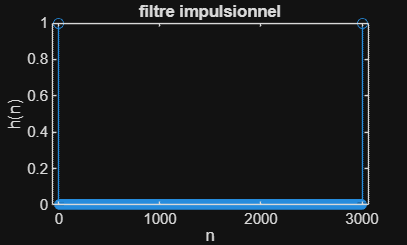

data = load('fcno03fz.mat');
s = data.fcno03fz(:);
N = length(s);
n = (0:N-1) / 8000;
k = [1 10 100 300 3000 10000];
k0=k(5);
h1 = filtre_impulsionnel(k0);

figure()
stem(0:k0, h1)
title('filtre impulsionnel')
xlabel('n')
ylabel('h(n)')

caractèrisation du filtre h(𝑘) = $\delta \left(k\right)+\delta \left(k-\textrm{k0}\right)$ :

     - RIF ( que 2 échantillons non nul)

    - Causal (h est non nul que pour n = 0 et n = n0 > 0

    - Stable car RIF

    - TFZ(h(n)) = H(Z) = $1+Z^{\;-\textrm{k0}}$

    - pas de pôles

    - zero complexe dépendant de k0

zn = $e^{j\pi \frac{2n+1}{\textrm{k0}}}$  avec $\left.m\in \lbrace 0,1,\ldotp \ldotp \ldotp ,\textrm{k0}-1\right\rbrace$

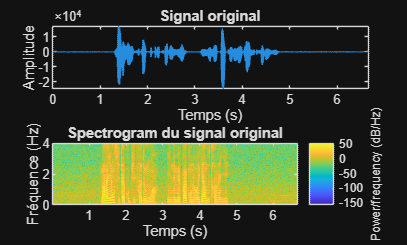

% Figure pour le signal original
figure()
subplot(2, 1, 1)
plot(n, s)
title('Signal original')
xlabel('Temps (s)')
ylabel('Amplitude')
xlim([0 max(n)]);
ylim([min(s) max(s)]);

subplot(2, 1, 2)
spectrogram(s, 256, [], [], 8000, 'yaxis');

title('Spectrogram du signal original')
xlabel('Temps (s)')
ylabel('Fréquence (Hz)');

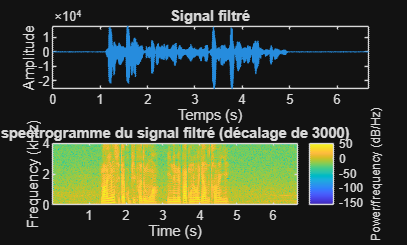


%filtrage
s_filtre = conv(s, h1, 'same');
% Affichage du signal filtré
figure()
subplot(2, 1, 1)
plot(n, s_filtre)
title('Signal filtré')
xlabel('Temps (s)')
ylabel('Amplitude')
xlim([0 max(n)]);
ylim([min(s_filtre) max(s_filtre)]);
subplot(2,1,2)
spectrogram(s, 256, [], [], 8000, 'yaxis');
title('spectrogramme du signal filtré (décalage de 3000)')

écoute pour k = 1, 10, 100, 3 000, 10 000

h = filtre_impulsionnel(1);

filtre_impulsionnel is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\iziou\Desktop\cours\filtre_num

Change the MATLAB current folder or add its folder to the MATLAB path.

s_filtre = conv(s, h1, 'same');
sound(s_filtre,8000);
